 imu : the model of imu including a,m,g

clear

IMU = imuSensor('accel-gyro-mag','SampleRate',100,'MagneticField',[16 0 27.712])

IMU =   imuSensor - 属性:

          IMUType: 'accel-gyro-mag'
       SampleRate: 100
      Temperature: 25
    MagneticField: [16 0 27.712]
    Accelerometer: [1×1 accelparams]
        Gyroscope: [1×1 gyroparams]
     Magnetometer: [1×1 magparams]
     RandomStream: 'Global stream'



m_local=[16 0 27.712];
IMU.Accelerometer = accelparams( ...
    'MeasurementRange',117.6, ...            % m/s^2
    'Resolution',0.001795, ...               % m/s^2 / LSB
    'TemperatureScaleFactor',0.002, ...      % % / degree C 
    'TemperatureBias',0.00196, ...           % m/s^2 / degree C
    'NoiseDensity',0.003,...                 %  噪声密度（rad/s)/√Hz
     "AxesMisalignment",0.6,...              % %（轴偏差）    
     'RandomWalk',0.0005);                   % 高斯白噪声（rad/s)*√Hz 

IMU.Magnetometer = magparams( ...
    'MeasurementRange',1200, ...             % uT
    'Resolution',0.3, ...                    % uT / LSB
    'TemperatureScaleFactor',0.1, ...        % % / degree C     
    'TemperatureBias',[0.1 0.1 0.1], ...     % uT / degree C
    'NoiseDensity',[0.6 0.6 0.9]/sqrt(100)); % uT / √Hz
IMU.Gyroscope =gyroparams( ...
    'MeasurementRange',8.7266, ...           % rad/s  测量范围
    'Resolution',0.00013323, ...             % (rad/s)/LSB （一个读取值代表多少rad/s）
    'AxesMisalignment',2, ...                % %（轴偏差）
    'NoiseDensity',8.7266e-05, ...           %  噪声密度（rad/s)/√Hz
    'TemperatureBias',0.34907, ...           %（rad/s)/℃
    'TemperatureScaleFactor',0.02, ...       % %/℃
    'AccelerationBias',0.00017809,...        % (rad/s)/(m/s^2)
    'RandomWalk',0.0005);                    % 高斯白噪声（rad/s)*√Hz 
IMU.Magnetometer

ans =   magparams - 属性:

    MeasurementRange: 1200       µT      
          Resolution: 0.3        (µT)/LSB
        ConstantBias: [0 0 0]    µT      
    AxesMisalignment: [0 0 0]    %       

       NoiseDensity: [0.06 0.06 0.09]    (µT)/√Hz
    BiasInstability: [0 0 0]             µT      
         RandomWalk: [0 0 0]             (µT)*√Hz

           TemperatureBias: [0.1 0.1 0.1]    (µT)/°C
    TemperatureScaleFactor: [0.1 0.1 0.1]    %/°C   


IMU.Gyroscope

ans =   gyroparams - 属性:

    MeasurementRange: 8.7266        rad/s      
          Resolution: 0.00013323    (rad/s)/LSB
        ConstantBias: [0 0 0]       rad/s      
    AxesMisalignment: [2 2 2]       %          

       NoiseDensity: [8.7266e-05 8.7266e-05 8.7266e-05]    (rad/s)/√Hz
    BiasInstability: [0 0 0]                               rad/s      
         RandomWalk: [0.0005 0.0005 0.0005]                (rad/s)*√Hz

           TemperatureBias: [0.34907 0.34907 0.34907]             (rad/s)/°C    
    TemperatureScaleFactor: [0.02 0.02 0.02]                      %/°C          
          AccelerationBias: [0.00017809 0.00017809 0.00017809]    (rad/s)/(m/s²)


IMU.Accelerometer

ans =   accelparams - 属性:

    MeasurementRange: 117.6            m/s²      
          Resolution: 0.001795         (m/s²)/LSB
        ConstantBias: [0 0 0]          m/s²      
    AxesMisalignment: [0.6 0.6 0.6]    %         

       NoiseDensity: [0.003 0.003 0.003]       (m/s²)/√Hz
    BiasInstability: [0 0 0]                   m/s²      
         RandomWalk: [0.0005 0.0005 0.0005]    (m/s²)*√Hz

           TemperatureBias: [0.00196 0.00196 0.00196]    (m/s²)/°C
    TemperatureScaleFactor: [0.002 0.002 0.002]          %/°C     


Motion : 1、the model of motion defined by accbody,angvelbody,using kinematicTrajectory.

              2、get the data of sensor from the model.


fs =100;
firstLoopNumSamples = fs*2;
secondLoopNumSamples = fs*2;
thirdLoopNumSampales=fs*2;
fourthLoopNumSampales=fs*3;
fifthLoopNumSampales=fs*3;
sixthLoopNumSampales=fs*8;

totalNumSamples =140*fs;


traj = kinematicTrajectory('SampleRate',fs);

accBody = zeros(totalNumSamples,3);
angVelBody = zeros(totalNumSamples,3);

angVelBody(1:140*fs,3)=4;


















[~,orientationNED,~,accNED,angVelNED] = traj(accBody,angVelBody);

[accelReadings,gyroReadings,magReadings] = IMU(accNED,angVelNED,orientationNED);



解算块

Q=cov(normrnd(0.2,1,[totalNumSamples 4]));
q=zeros(totalNumSamples,3);
[q,~,~,~]=jiesuan(accelReadings',gyroReadings',magReadings',Q,fs,m_local');

输出块

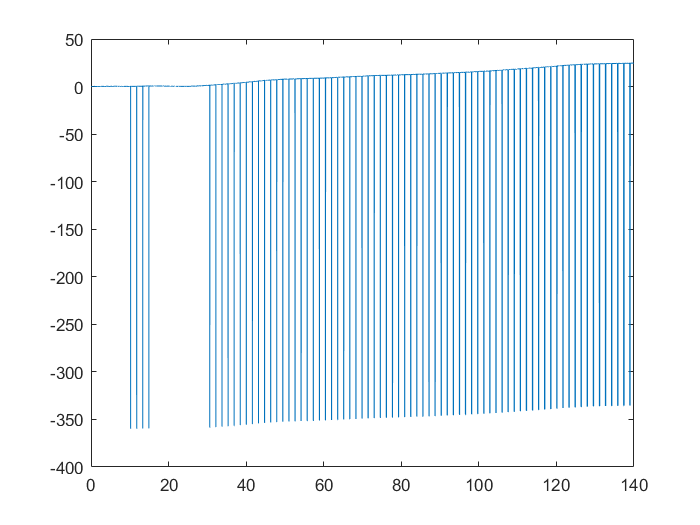

t=(0:(totalNumSamples-1)).'/fs;
q_filter=quaternion(q');

qDistDefault=rad2deg(dist(orientationNED,q_filter));

figure
eu_de=eulerd(orientationNED,'ZYX',"point");
euler_angle=eulerd(q_filter,'ZYX',"point");
e1=euler_angle(:,1);
e2=eu_de(:,1);

h1=euler_angle(:,2);
h2=eu_de(:,2);

o1=euler_angle(:,3);
o2=eu_de(:,3);

e=e1-e2;

plot(t,e)

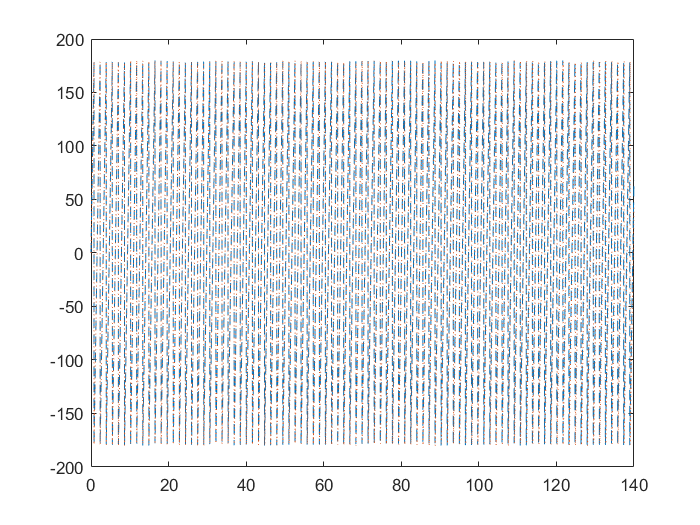

plot(t,e1,'--',t,e2,':')

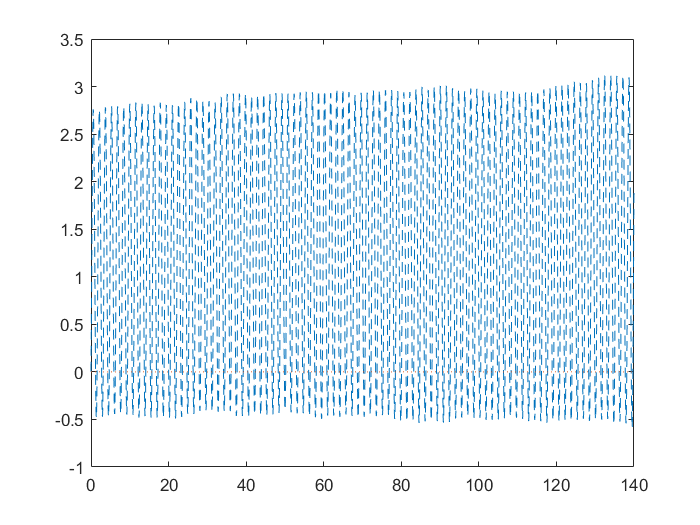

plot(t,h1,'--',t,h2,':')

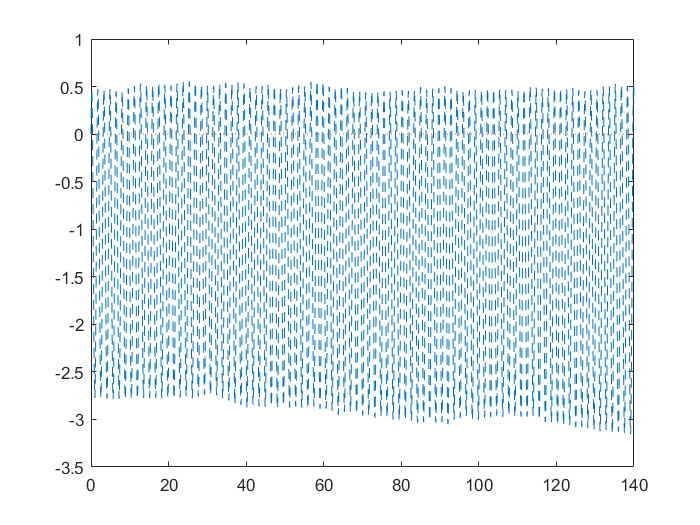

plot(t,o1,'--',t,o2,':')